clc;
clear;
format long

tic;

## Numerical methods 

- ***Graphical ***(done)

- ***Hit & Trial ***(done)

- ***Bracketing***

- Bisection (done)

- False Position (done)

- ***Open***

- Secant (done)

- Newton (done)

- Muller

- Fixed Point iteration

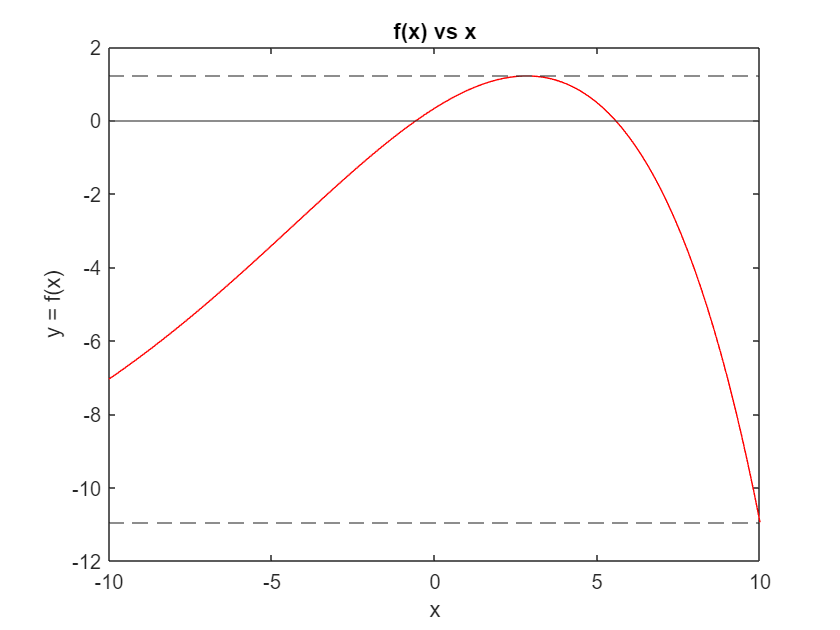

% Graphical

x = linspace(-2, 3);
f = 3*x + sin(x) - exp(x);
range = linspace(-10, 10);

plot(range, f, 'r');

yline(0);
ymax = max(f);
ymin = min(f);

title("f(x) vs x");
ylabel("y = f(x)");
xlabel("x");

yline([ymax ymin], '--');
ylim padded

## Bisection

% Bisection

% Function
f = @(x) 3 * x + sin(x) - exp(x);

% Initial Guesses
x0 = 0;
x1 = 1;

% Tolerance
TOL = 1e-6;

root = bisection(f, x0, x1, TOL);

No. of iterations = 19


root

root =    0.360420227050781


## Secant

% Secant
root = secant(f, x0, x1, TOL);

No. of iterations = 4


root

root =    0.360421703368560


## False Position

% False Position

root = falsePos(f, x0, x1, TOL);

No. of iterations = 17


root

root =    0.360421702960324


## Newton

fd = @(x) 3 + cos(x) - exp(x);

root = newton(f, fd, x0, TOL);

x1 =    0.333333333333333


No. of iterations = 3


root

root =    0.360421702960324


## Fixed Point iteration

g = @(x) x.^2 - 2*x - 3;
h = @(x) x;
i = @(x) 3/(x-2);
j = @(x) (x.^2-3)/2;
k = @(x) sqrt(2*x + 3);

## Multi Newton

inp = @(ci0, ci1, v) 200*ci0 - 200*ci1 - v*ci1.^2;
X0 = [1;2;3;4;5];

% root = multiNewton(@INP, X0, TOL);
norm(INP(X0))

ans =      1.180911327111397e+03


## Symbolic ToolBox

syms x y

y = x^3;
y1 = diff(y)

$$y1 = 3\,x^{2}$$

y2 = diff(y, 2)

$$y2 = 6\,x$$

pretty(y);

 3
x



int_y = int(y)

$$int\_y = \frac{x^{4}}{4}$$

val = int(y, x, 0, 1)

$$val = \frac{1}{4}$$

double(val)

ans =    0.250000000000000


single(val)

ans = single
   0.2500000


syms x1 x2
S = [x1 + x2 == 3, x1 - x2 == 1];
S

$$S = \left(\begin{array}{cc} x_{1}+x_{2}=3 & x_{1}-x_{2}=1 \end{array}\right)$$

Sol = solve(S, [x1 x2])

Sol = struct with fields:
    x1: 2
    x2: 1


Sol.x1

$$ans = 2$$

syms y(x) x

eqn = diff(y, 1) + 6*x.^2*y == 2*x.^2*y.^(1/2)

$$eqn(x) = 6\,x^{2}\,y\left(x\right)+\frac{\partial }{\partial x}y\left(x\right)=2\,x^{2}\,\sqrt{y\left(x\right)}$$

cond = y(0) == 0;
dsolve(eqn)

$$ans = \left(\begin{array}{c} {\left({\mathrm{e}}^{C_{1}-x^{3}}+\frac{1}{3}\right)}^{2}\\ 0\\ \frac{1}{9} \end{array}\right)$$

dsolve(eqn, cond)

$$ans = \left(\begin{array}{c} {\left({\mathrm{e}}^{-x^{3}-\log\left(3\right)}-\frac{1}{3}\right)}^{2}\\ 0 \end{array}\right)$$

timeTaken = toc;
disp("Executed in " + timeTaken + " seconds.")

Executed in 3.2231 seconds.


function root = bisection(f, x0, x1, TOL)

    counter = 0;

    if (f(x0)* f(x1) > 0)

        disp("Wrong guesses");
        root = false;

    elseif (f(x0) * f(x1) == 0)

        if f(x0) == 0
            root = x0;
        else
            root = x1;
        end

    else
        x2 = (x0 + x1)/2;

        while abs(x0 - x1) > 2 * TOL
            
            if (f(x0)* f(x2) < 0)
                x1 = x2;
            else
                x0 = x2;
            end
            
            x2 = (x0 + x1)/2;
            counter = counter + 1;
        end

        root = x0;
        disp("No. of iterations = "+ counter);
    end
end

function root = secant(f, x0, x1, TOL)
    
    if (abs(f(x1)) < abs(f(x0)))
        temp = x1;
        x1 = x0;
        x0 = temp;
    end
    
    x2 = x1 - f(x1) * (x1 - x0)/ (f(x1) - f(x0));
    counter = 0;

    while abs(f(x2)) > 2 * TOL
        
        x1 = x0;
        x0 = x2;

        x2 = x1 - f(x1) * (x1 - x0)/ (f(x1) - f(x0));
        counter = counter + 1;
    end

    root = x2;
    disp("No. of iterations = "+ counter);

end

function root = falsePos(f, x0, x1, TOL)

    x2 = x1 - (f(x1) * (x1 - x0)/(f(x1) - f(x0)));
    counter = 0;

    while abs(x0 - x1) > 2 * TOL

        if (f(x0) * f(x2) < 0)
            x1 = x2;
        else
            x0 = x2;
        end
        
        x2 = x1 - (f(x1) * (x1 - x0)/(f(x1) - f(x0)));
        counter = counter + 1;
    end

    root = x0;
    disp("No. of iterations = "+ counter);

end

function root = newton(f, fd, x0, TOL)

    x1 = x0 - (f(x0) / fd(x0))
    counter = 0;

    if f(x0) ~= 0 && fd(x0) ~= 0

        while abs(x1-x0) > TOL || abs(f(x1)) > TOL
            x0 = x1;
            x1 = x0 - f(x0)/fd(x0);
            counter = counter + 1;
        end
        
        root = x1;

    elseif f(x0) == 0
        root = x0;
    else
        disp("Wrong guess!")
        root = false;
    end

    disp("No. of iterations = "+ counter);
end

function root = fixPointIter(f, x0, TOL)

    
end

function root = multiNewton(F, X0, TOL)

    X1 = X0 - jacob(X0)\ F(X0);
    counter = 0;
    while norm(X1-X0) > TOL || norm(F(X1)) > TOL
        X0 = X1;
        X1 = X0 -  jacob(X0)\ F(X0);
        counter = counter + 1;
    end

    root = X1;
    disp("No. of iterations = "+ counter);
end

function y = INP(X)

    y = zeros(5, 1);

    for i= 1 : 5

        if i==1
            y(i) = 1000 - 200 * X(i) - X(5) * X(i).^2;
        elseif i==5
            y(i) = 200 * X(i-1) - 40 - X(5) * 0.25;
        else
            y(i) = 200 * X(i-1) - 200 * X(i) - X(5) * X(i).^2;
        end

    end
    
end

function z = jacob(X)
    syms a b c d e
    
    f = [1000 - 200 * a - e * a.^2;
        200 * a - 200 * b - e * b.^2;
        200 * b - 200 * c - e * c.^2;
        200 * c - 200 * d - e * d.^2;
        200 * d - 40 - 0.25 * e];

    z = jacobian(f, [a b c d e]);

    z = subs(z, [a; b; c; d; e], X);

end